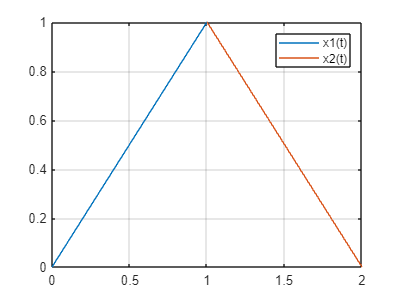

syms t
x=t*(heaviside(t)-heaviside(t-1))+(2-t)*(heaviside(t-1)-heaviside(t-2));

x1 = t;
x2 = 2-t;

figure
fplot(x1, [0 1])
hold on
fplot(x2, [1 2])
grid on
legend('x1(t)', 'x2(t)')
hold off

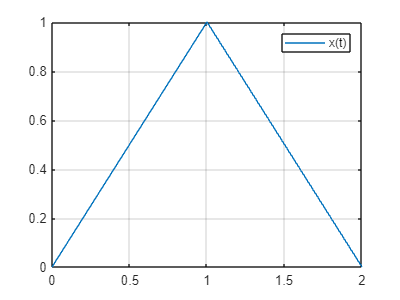


T = 2;
w = 2*pi/T;
t0 = 0;

figure
fplot(x,[0 2])
legend('x(t)');
grid on

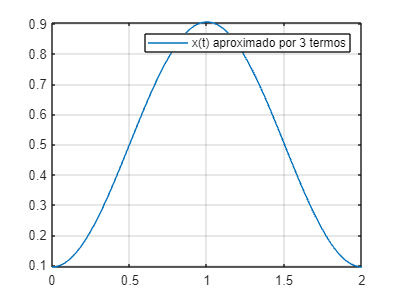

Px = 1/T * int(abs(x)^2, t, t0, t0+T);
Px1 = 1/T * int(abs(x1)^2, t, 0, 1);
Px2 = 1/T * int(abs(x2)^2, t, 1, 2);
Px1 = double(Px1);
Px2 = double(Px2);
Px = Px1 + Px2;

%Aproximação por 3 termos 
k = -1:1;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx3 = sum(a.*exp(j*k*w*t));
figure
fplot(xx3, [0 2])
legend('x(t) aproximado por 3 termos')
grid on

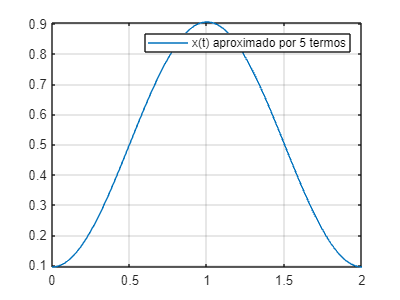

P3 = sum(abs(a).^2);
per3 = P3 /Px;
per3R = double(per3) * 100;

%Aproximação por 5 termos
k = -2:2;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx5 = sum(a.*exp(j*k*w*t));
figure
fplot(xx5, [0 2])
legend('x(t) aproximado por 5 termos')
grid on

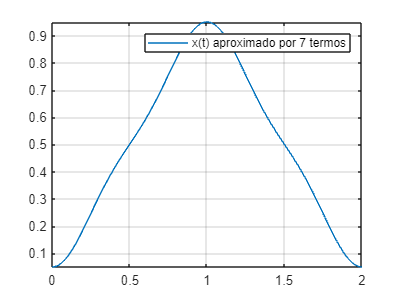

P5 = sum(abs(a).^2);
per5 = P5 /Px;
per5R = double(per5) * 100;

%Aproximação por 7 termos 
k = -3:3;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx7 = sum(a.*exp(j*k*w*t));
figure
fplot(xx7, [0 2])
legend('x(t) aproximado por 7 termos')
grid on

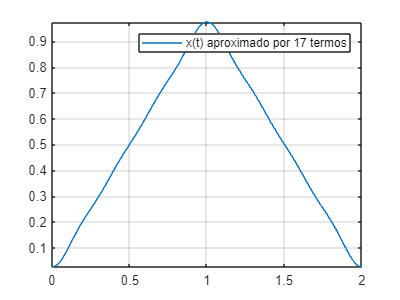

P7 = sum(abs(a).^2);
per7 = P7 /Px;
per7R = double(per7) * 100;

%Aproximação por 17 termos
k = -8:8;
a = 1/T*int(x*exp(-j*k*w*t), t, t0, t0+T);
xx17 = sum(a.*exp(j*k*w*t));
figure
fplot(xx17, [0 2])
legend('x(t) aproximado por 17 termos')
grid on

P17 = sum(abs(a).^2);
per17 = P17 /Px;
per17R = double(per17) * 100;